# 9.2 Adaptative Filtering

Alexandre Rey, MSE, MA-StatDig, 2022

clear;

importedData = load("ex92_data.mat");
addpath('../functions/');

## Ex 9.2 : Linear prediction using RLS on non stationary process

The goal of this exercice is to compare the LMS and the RLS algorithm for a one-step prediction of a non-stationary process.


$$x\left\lbrack n\right\rbrack =-a_n \left\lbrack 1\right\rbrack \cdot \;x\left\lbrack n-1\right\rbrack -a_n \left\lbrack 2\right\rbrack \cdot \;x\left\lbrack n-2\right\rbrack +v\left\lbrack n\right\rbrack$$


Where the coefficients $a_n[k]$ are changing accross time:


$$a_n \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{ll}
a_n \left\lbrack 1\right\rbrack =-1\ldotp 2728\;\;\;\;n\in \left\lbrack 0,100\right\rbrack ,\;\;\;\; & a_n \left\lbrack 1\right\rbrack =0\;\;\;\;n\in \left\lbrack 101,200\right\rbrack \\
a_n \left\lbrack 2\right\rbrack =0\ldotp 81\;\;\;\;\;n\in \left\lbrack 0,100\right\rbrack , & a_n \left\lbrack 2\right\rbrack =0\ldotp 81\;\;\;\;\;n\in \left\lbrack 100,200\right\rbrack 
\end{array}\right.$$


To remind, the scheme of a one-step prediction is:

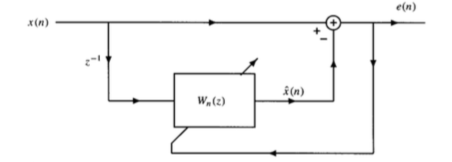

Therefore suppose we consider an adaptive linear predictor of the form:


$$\hat{x} \left\lbrack n\right\rbrack =w_{n\;} \left\lbrack 1\right\rbrack x\left\lbrack n-1\right\rbrack +w_{n\;} \left\lbrack 2\right\rbrack x\left\lbrack n-2\right\rbrack$$


The goal is to design the prediction using the two adaptive algorithms (RLS and LMS) and to compare the performance.

## Data Generation

### Parameter

Let's set the parameters:

aFirst = [-1.2728, 0.81];
aSecond = [0, 0.81];
N = 200;
n = 0:N-1;
SigmaNoise = 1;

disp(table(aFirst, aSecond, N, SigmaNoise));

          aFirst           aSecond      N     SigmaNoise
    __________________    _________    ___    __________

    -1.2728       0.81    0    0.81    200        1     



### Generation

Let's generate the non-stationary process. The following is showing the signal and the coefficients accross time of the autoregressive process. You can directly load the signal **x**[n] from the data file as well the autoregressive coefficient accross time **A**.

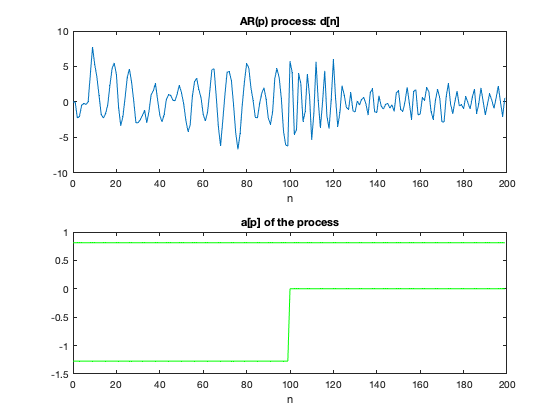

% generate non-stationary process randomly
% x = zeros(N,1)
% A = zeros(2,N)
% A(:,1) = aFirst;
% A(:,2) = aFirst;
% 
% for n = 3:N
%     if n<= 100
%         a = aFirst
%     else
%         a = aSecond
%     end
%     A(:,n) = a;
%     x(n) = - a(1)*x(n-1) - a(2)*x(n-2) + v(n)
% end

% import from teacher mat-file
A = importedData.A;
x = importedData.x;

tiledlayout(2,1);
nexttile;
    plot(n, x);
    title('AR(p) process: d[n]');
    xlabel('n');
nexttile;
    plot(n, A(1,:), 'g', ...
         n, A(2,:), 'g');
    title('a[p] of the process');
    xlabel('n');

## Adaptive filter

#### Recursive autocorrelation

As seen in theory, the RLS algorithm can be expressed by computing the weighted deterministic autocorrelation matrix for $x[n]$ and the deterministic cross-correlation between $d[n]$ and $x[n]$.


$${\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}}} \left(n\right){\mathit{\mathbf{w}}}_{\mathit{\mathbf{n}}} ={\mathit{\mathbf{r}}}_{\textrm{rdx}} \left(n\right)$$



$${\mathit{\mathbf{w}}}_{\mathit{\mathbf{n}}} ={\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}}}^{-1} \left(n\right)\cdot \;{\mathit{\mathbf{r}}}_{\textrm{rdx}} \left(n\right)$$


The deterministic autocorrelation is computed:


$${\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}}} \left(n\right)=\sum_{i=0}^n \lambda {\;}^{n-i} {\mathit{\mathbf{x}}}^* \left\lbrack i\right\rbrack {\mathit{\mathbf{x}}}^T \left\lbrack i\right\rbrack ={\lambda \mathit{\mathbf{R}}}_{\mathit{\mathbf{x}}} \left(n-1\right)+{\mathit{\mathbf{x}}}^* \left\lbrack i\right\rbrack {\mathit{\mathbf{x}}}^T \left\lbrack i\right\rbrack$$


And the determinstic crosscorrelation is computed:


$${\mathit{\mathbf{r}}}_{\textrm{rdx}} \left(n\right)=\sum_{i=0}^n \lambda {\;}^{n-i} d\left\lbrack i\right\rbrack {\mathit{\mathbf{x}}}^* \left\lbrack i\right\rbrack ={\lambda \;\mathit{\mathbf{r}}}_{\textrm{rdx}} \left(n-1\right)+d\left\lbrack i\right\rbrack {\mathit{\mathbf{x}}}^* \left\lbrack i\right\rbrack$$


Where $\mathit{\mathbf{x}}\left\lbrack i\right\rbrack$ is the sample vector:


$$\mathit{\mathbf{x}}\left\lbrack i\right\rbrack =\left\lbrack \begin{array}{c}
x\left\lbrack i\right\rbrack \\
x\left\lbrack i-1\right\rbrack \\
\vdots \\
x\left\lbrack i-p\right\rbrack 
\end{array}\right\rbrack$$


And for a predictive filter, the desired output $d[i]$ is simply the futur sample:


$$d\left\lbrack i\right\rbrack \;=\;x\left\lbrack i+1\right\rbrack$$


Let's start to compute the filter coefficients $w$ using this recursive autocorrelation. For each sample $n$, a new vector of coefficient $w$ is computed. The number of coefficient must be equal to $n_c = 2$ and $\lambda=0.98$. The vector $w$ can be saved in a matrix $W(n,:)$ of preinitialize `W``=zeros(N-1,nc)` where $N$ is the total number of sample.

nc = 2;
Nd = N-nc+1;
nd = (1:Nd)';  % n reduce according to nc, used for graphs

lambda = 0.98;
[W_rls, E_rls] = myRLS(x(1:end-nc+1), x(1+nc-1:end), nc, lambda);

Compare the computed coefficients **W** to the optimum coefficients which are simply the ${w_{\textrm{nOptim}} \left\lbrack k\right\rbrack \;=\;-a}_n \left\lbrack k\right\rbrack$

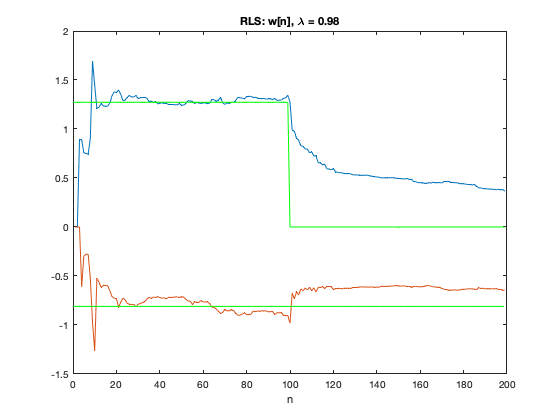

figure;
    plot(nd, W_rls(:,1), ...
         nd, W_rls(:,2), ...
         n, -A(1,:), 'g', ...
         n, -A(2,:), 'g');
    hold off;
    title(['RLS: w[n], \lambda = ' num2str(lambda)]);
    xlabel('n');

### Design RLS

To avoid this inverse of ${\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}}} \left(n\right)$ accross time, we could compute the inverse recursively as well. For that, you can use the RLS calculation given in the theory and implement the function myRLS(). Then, you can compare the found coefficients to the optimum coefficients. Use as previously  nc = 2 and $\lambda=0.98$.

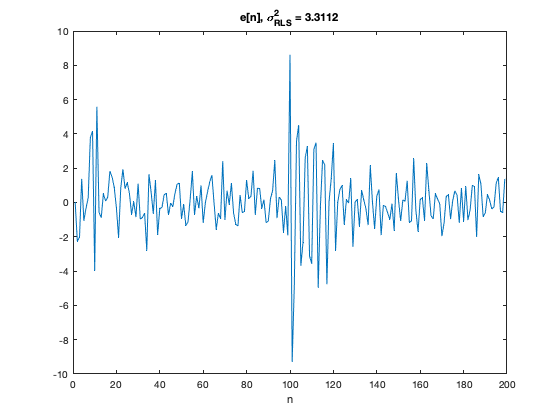

figure;
    plot(nd, E_rls);
    title(['e[n], \sigma^2_{RLS} = ' num2str(var(E_rls))]);
    xlabel('n');

### Compare to LMS

Finally, compare the coefficients with the LMS algorithm by using $\mu =0\ldotp 02$.

mu = 0.02;
[W_lms, E_lms] = myLMS(x(1:end-nc+1), x(1+nc-1:end), mu, nc);

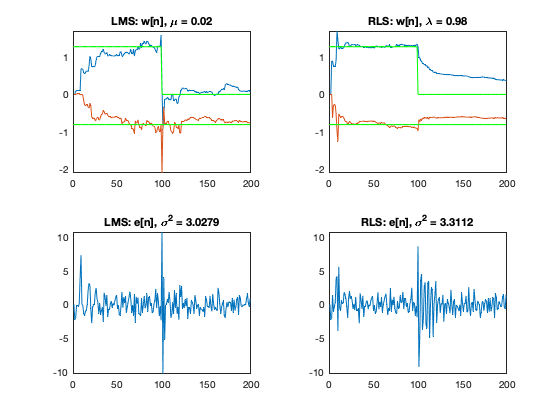

figure;
tiledlayout(2,2);
t1=nexttile;
    plot(nd, W_lms(:,1), ...
         nd, W_lms(:,2), ...
         n, -A(1,:), 'g', ...
         n, -A(2,:), 'g');
    title(['LMS: w[n], \mu = ' num2str(mu)]);
t2=nexttile;
    plot(nd, W_rls(:,1), ...
         nd, W_rls(:,2), ...
         n, -A(1,:), 'g', ...
         n, -A(2,:), 'g');
    title(['RLS: w[n], \lambda = ' num2str(lambda)]);
t3=nexttile;
    plot(nd, E_lms);
    title(['LMS: e[n], \sigma^2 = ' num2str(var(E_lms))]);
t4=nexttile;
    plot(nd, E_rls);
    title(['RLS: e[n], \sigma^2 = ' num2str(var(E_rls))]);
linkaxes([t1 t2 t3 t4], 'x');
linkaxes([t1 t2], 'y');
linkaxes([t3 t4], 'y');
t1.YLim = [min([W_lms, W_rls],[],'all') max([W_lms, W_rls],[],'all')];
t3.YLim = [min([E_lms, E_rls],[],'all') max([E_lms, E_rls],[],'all')];